# This program is used to simulate regular grids of connect springs with free rotation

## generate geometry

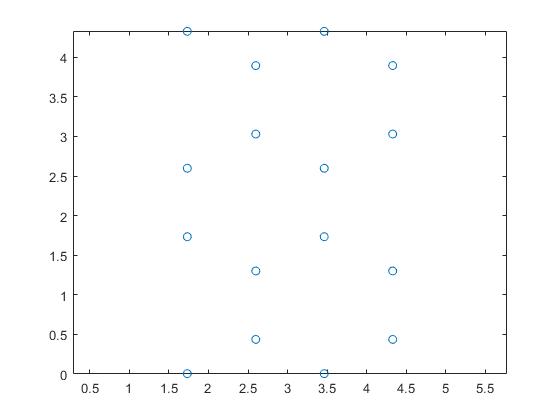

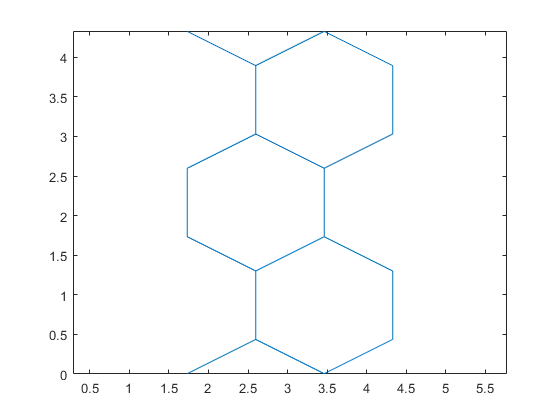

% [position,connectivity, springs] = generategeometry("kagome",20,50,1);
% [position,connectivity, springs] = generategeometry("triangle",50,50,1);
clear;
tic
[position,connectivity, springs] = generategeometry("hexigonal",3,3,1);  

toc

Elapsed time is 0.377289 seconds.


%[position,connectivity] = generaterandom(50,50,1,1.5);                     % not made yet

## Intialize spring length and anchored points

mymodel = initializemymodel(position,connectivity,springs,"edges");

## Test stiffness at a point

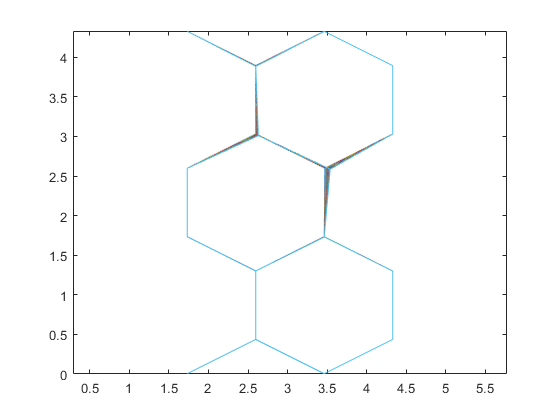

tic
[stiffnesses,mymodel2] = amrliketest(0.1, 0, 3.5,3, 20, mymodel, "linear");

toc

Elapsed time is 0.295136 seconds.


## display model

%displaymymodel(mymodel,"simple");              
displaymymodel(mymodel2,"strain");                                         % not sure what it does, just ported over from old code

## change intial length

%changespringlengthrandom();                                                % not made yet 
%photocrosslinkregion();                                                    % not made yet

## save the current model

userinput = input('Enter file name: ' , 's');                               % pick a good name
save(userinput,'mymodel')